addpath(genpath(pwd))
addpath(genpath('Z:\01_Codes_Projects\Torino_syRe'))

JMAG에서 특정 kW에 대해서 Q값 구하기

해당 d^2L 값 

전류밀도

온도

## Stipetic 코드화 

- Syre와 mcb 코드 최대한 활용하기

### 레퍼런스 값들

값 가져오기

- MotorCAD

- mcb (JMAG)

- JMAG Express (SingleValue)

### Scaling

scaleMachine              % syRe : Geometry
devScaleMethodStiepetic   % stipetic 논문에서 수식 발췌 

someSlotArea=842.6/31.04
SatuMapData.CurrentDensityRMS=SatuMapData.Stator_Current_Line_RMS/someSlotArea

%% Scale Coefficient
Factor.k_Axial     =1.2;
Factor.k_Radial    =2;
% % k_Winding   =2;
n_c = 12
a_p = 4
Factor.k_Winding = (n_c/a_p)/(n_c_ref / a_p_ref)
%
TeslaSPlaidGeometry.ll =132.5% l_stk,ref의 값
TeslaSPlaidGeometry.D_out =222; % D_out,ref의 값
TeslaSPlaidGeometry.turnperCoil=10; % turn per Coil
TeslaSPlaidGeometry.ParallelPath=4
Scaled = devScaleMethodStiepetic(Factor,SatuMapData,TeslaSPlaidGeometry)

### 특성 비교(TN 계산 !! -> 효율맵) 

방법론별

- Dankai 복습 -Gaussian Model -devMBCFromDankai.mlx 참조

- 테이블로 만들어서 Filter 걸기 (Physics 모델)

- SyRe 코드

데이터소스별 

- Express (1point와 여러포인트 확장)

- MotorCAD

최종목표

- D^2L과 TRV 등 사이징 함수 비교

- Q와 관련된 사이징 - 얘기 어디서? syre 1번 , mmm에는 있나?

                - > 이면에 있는 논의 찾기 syRE    : very simple LPTN으로 

- Scaling Method와 DSE Method 비교 : 

evil is in Detail. Quantization in System Level 시각 

#### 테이블로 만들어서 Filter 걸기!

%Flux 
tempPlotMCADFluxMap(Scaled);
tempPlotMCADFluxMap(MotorCADFEA);

#### 토크 방정식

% MotorCADFEA=createTorqueDqMap(MotorCADFEA,Input);
%Torque
tempPlotMCADTorqueMap(Scaled,Input);
tempPlotMCADTorqueMap(MotorCADFEA,Input);



#### [TB]전압방정식

% Vds_t = Input.Rs*i_d - Wr*Lamda_qs;
% Vqs_t = Input.Rs*i_q + Wr*Lamda_ds;
% Vabs_s = sqrt(Vds_t.^2 + Vqs_t.^2);


#### [WIP]SyRe Code

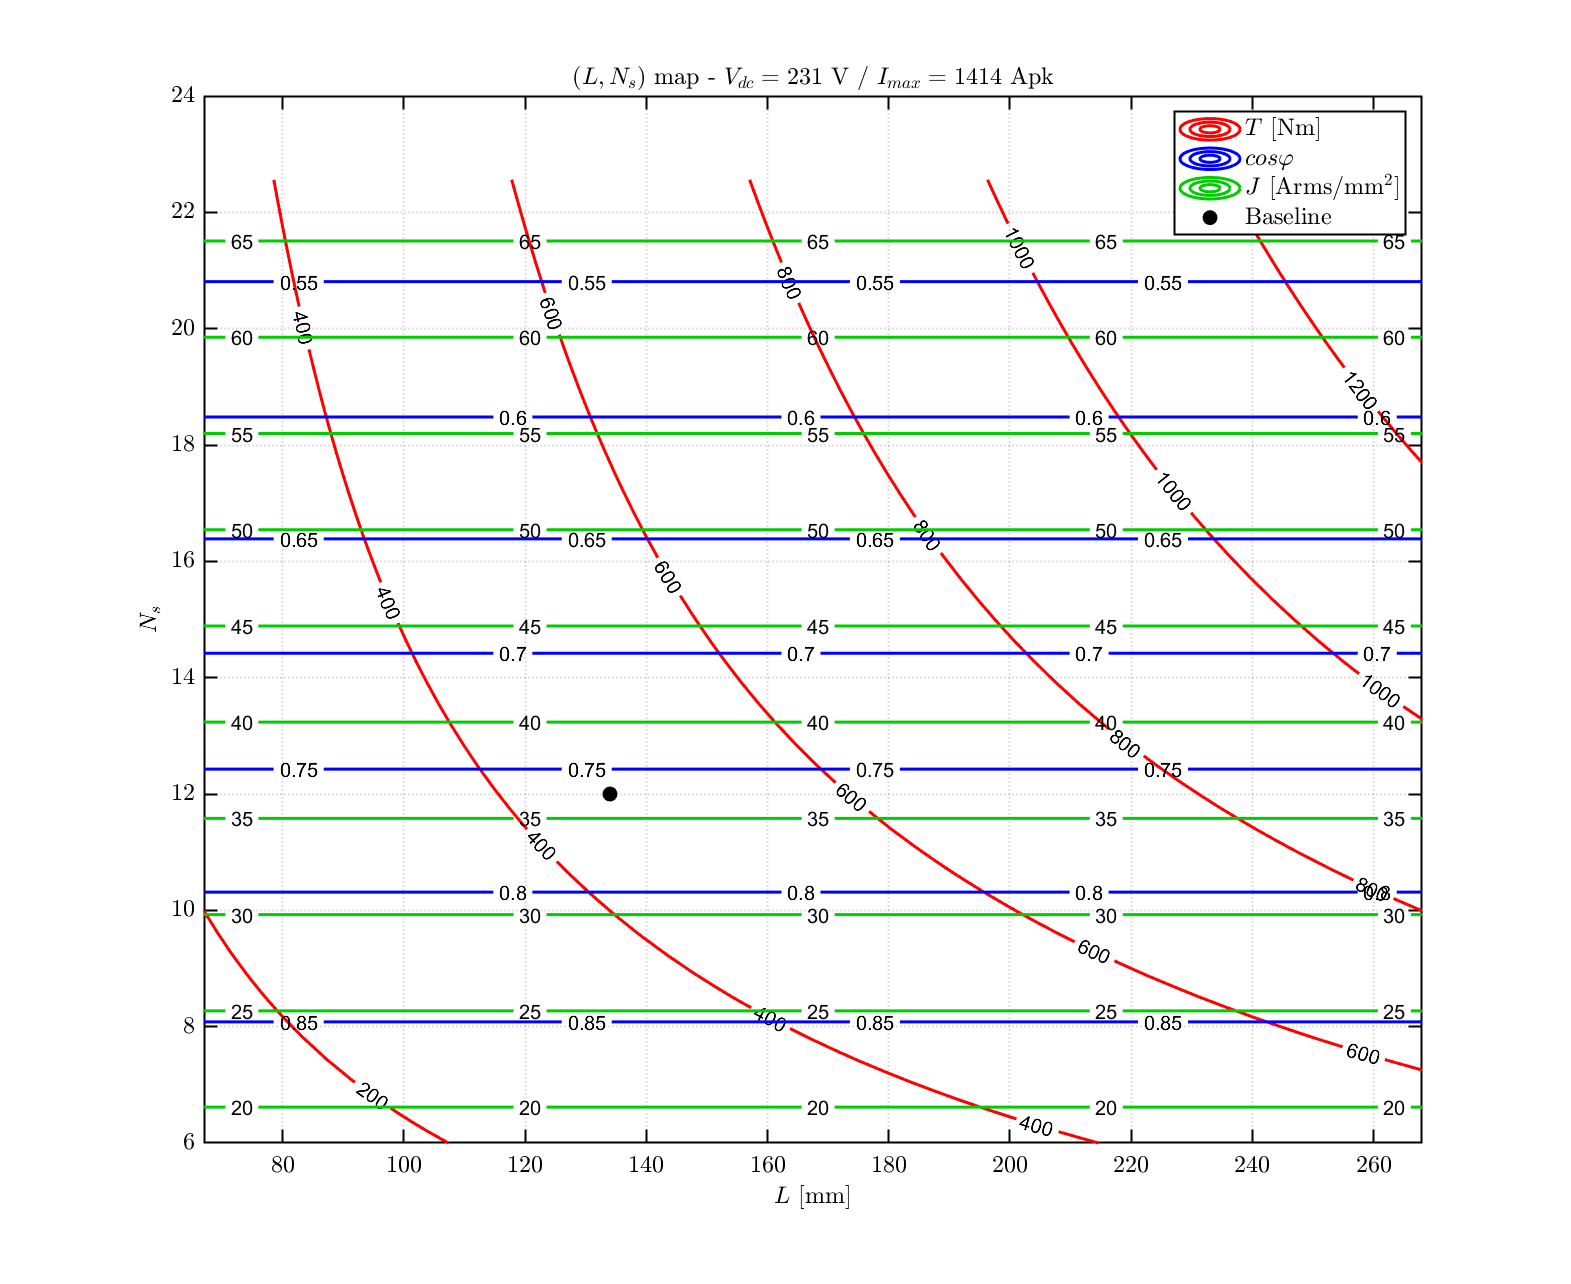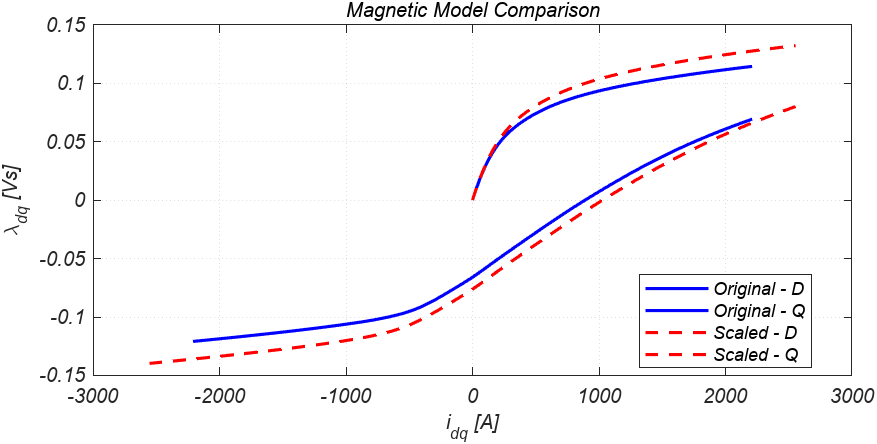

% load dq Map

% Model Scaling  
% Scale Map -> Scale Model 
% Scale Map : 

% Pareto Point From Scaled Model 


Scaled 된 Model의 TN은 비활성화 (Why?

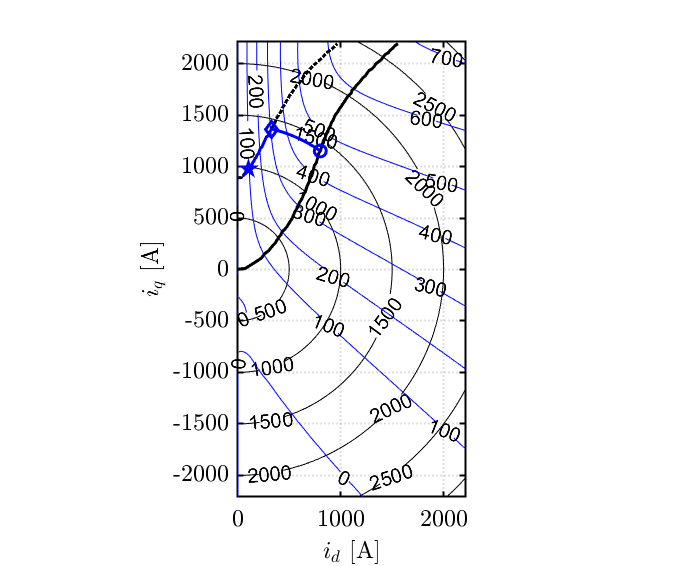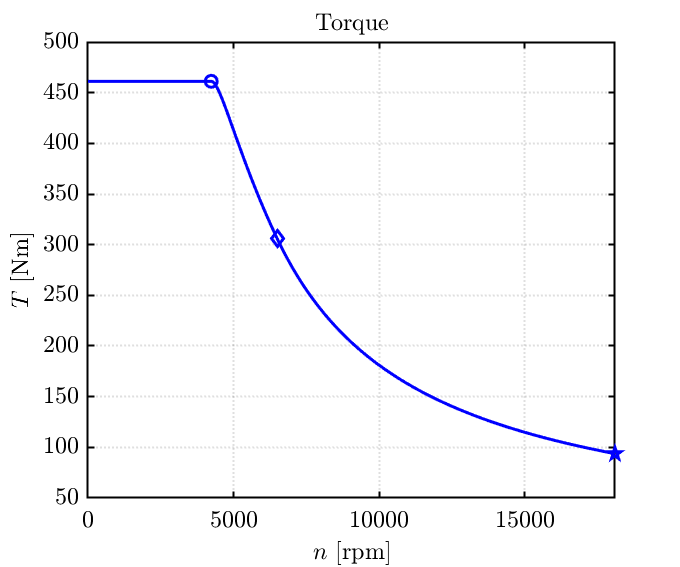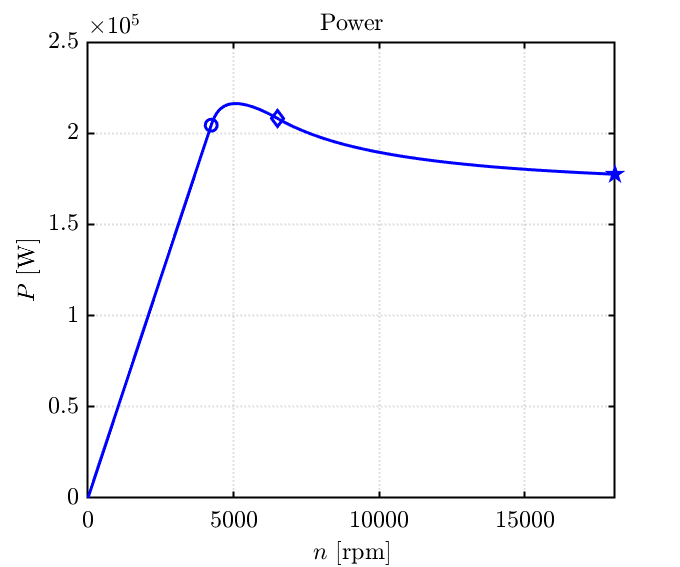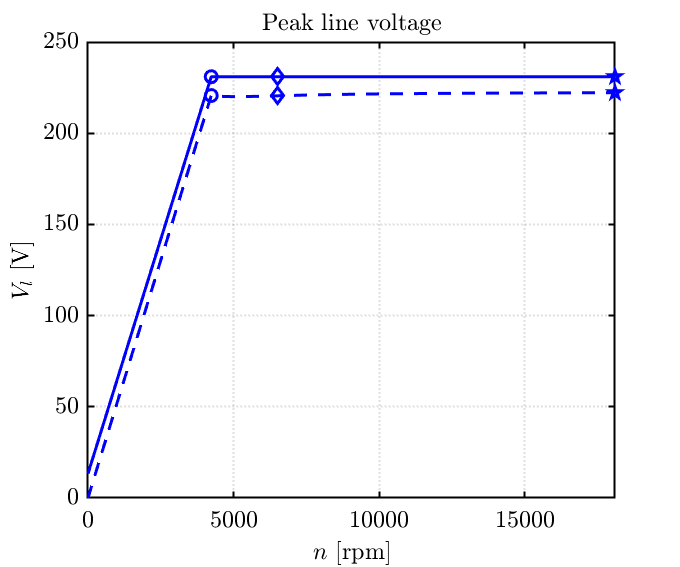

% MotorCAD로 export? 



## 온도 해석

방법들 나열

## 최적화 - 전압방정식은 제약조건, 효율최대, 원하는 토크와 오차가 최소가 되는 id,iq값찾기

사용법

% Define the objective function to maximize efficiency
objective = @(x) -Efficiency(x);

% Define the nonlinear constraint function for voltage equation
nonlcon = @(x) VoltageEquation(x);

% Initial guess for id and iq
x0 = [0.5, 0.5];

% Define lower and upper bounds for id and iq
lb = [-1, -1];
ub = [1, 1];

% Solve the optimization problem using fmincon
options = optimoptions('fmincon', 'Algorithm', 'sqp');
[x_opt, fval] = fmincon(objective, x0, [], [], [], [], lb, ub, nonlcon, options);

% Display the optimized id and iq values
disp(['Optimized id: ', num2str(x_opt(1))]);
disp(['Optimized iq: ', num2str(x_opt(2))]);
disp(['Maximum Efficiency: ', num2str(-fval)]);


function efficiency = Efficiency(x)
    % Define your efficiency calculation here based on id and iq
    % For example: efficiency = some_function(x(1), x(2));
end

function voltage_eq = VoltageEquation(x)
    % Define the voltage equation as a constraint
    % For example: voltage_eq = some_equation(x(1), x(2)) - V_ref;
end
